Function FItting with NN

clc;
close all;
clear ;

Import the Data

data = cell2mat(struct2cell(load('data_NN.mat')))

data =    -2.0000   -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766
         0    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978  

x = data(1:3,1:1000)%Take the input from the data_NN.mat

x =    -2.0000   -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766
         0    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978   -1

y = data(1:3,2:1001)%Take the output from the data_NN.mat

y =    -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766   -3.0184
    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978   -1.9687   -2

Set the bounds for the normalized data

top = 0.9

top = 0.9000

bottom = 0.1

bottom = 0.1000

Normalize the data

data_min = min(data(:))

data_min = -75.0001

data_max = max(data(:))

data_max = 0.0372

norm_data = (((top-bottom)*(data-data_min))/(data_max-data_min))+bottom

norm_data =     0.8783    0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668
    0.8996    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8

Normalize the input data

normx = norm_data(:,1:1000)

normx =     0.8783    0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668
    0.8996    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794 

Normalize the output data

normy = norm_data(:,2:1001)

normy =     0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668    0.8674
    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794    0.8786 

Create the NN

hidden_neurons = [5,5]%Set the hidden neurons

hidden_neurons =      5     5


net = fitnet(hidden_neurons);%Create the NN

net.divideParam.trainRatio = 0.7;%Training Ratio
net.divideParam.valRatio = 0.2;%Validation Ratio
net.divideParam.testRatio = 0.1;%Test Ratio

net.trainParam.epochs = 1000;%Number of epochs

%Choose the training function
net.trainFcn = 'trainlm'; %Levenberg-Marquardt
%net.trainFcn = 'trainbr'; %Bayesian Regularization
%net.trainFcn = 'traingd'; %Gradient Descent
%net.trainFcn = 'traingdm'; %Gradient Descent with Momentum

Train the NN

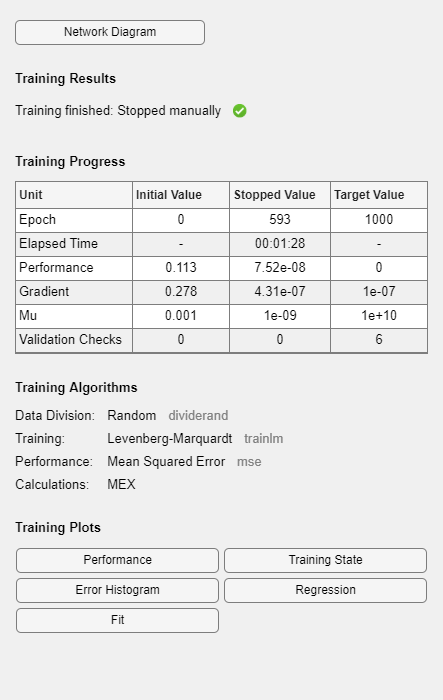

[net,tr] = train(net,normx,normy);

Test the NN for the given data

test = net(normx)

test =     0.8777    0.8774    0.8770    0.8766    0.8762    0.8758    0.8754    0.8749    0.8745    0.8740    0.8735    0.8731    0.8726    0.8721    0.8715    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8665    0.8660    0.8656    0.8652    0.8648    0.8644    0.8641    0.8637    0.8635    0.8632    0.8630    0.8628    0.8627    0.8627    0.8627    0.8628    0.8629    0.8631    0.8634    0.8638    0.8642    0.8647    0.8652    0.8658    0.8664    0.8670
    0.8997    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8989    0.8987    0.8985    0.8982    0.8980    0.8976    0.8973    0.8969    0.8965    0.8961    0.8956    0.8951    0.8946    0.8940    0.8933    0.8926    0.8918    0.8910    0.8902    0.8893    0.8884    0.8875    0.8866    0.8857    0.8848    0.8839    0.8830    0.8822    0.8814    0.8806    0.8798    0.8791  

Test for 200 steps with initial input x0 = [-1.9 0 -0.9]

output = []%Initialize the output matrix


output =

     []



x0 = [-1.9 ; 0 ; -0.9]%Initial Value

x0 =    -1.9000
         0
   -0.9000


target = normy(:,1:200)%Set our target

target =     0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668    0.8674
    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794    0.8786

Normalize x0

normx0 = (((top-bottom)*(x0-data_min))/(data_max-data_min))+bottom

normx0 =     0.8793
    0.8996
    0.8900


Test the NN

normxk = net(normx0);%Calculate the next value
output = [output normxk]%Add xk to the output matrix

output =     0.8788
    0.8997
    0.8897


%Calculate the rest values
for i=1:199
    x_new =  net(output(:,end));
    output =  [output x_new];
end
output

output =     0.8788    0.8782    0.8777    0.8772    0.8766    0.8761    0.8755    0.8750    0.8744    0.8738    0.8733    0.8727    0.8722    0.8717    0.8711    0.8706    0.8701    0.8696    0.8691    0.8687    0.8682    0.8678    0.8674    0.8670    0.8666    0.8663    0.8659    0.8656    0.8653    0.8650    0.8647    0.8644    0.8641    0.8638    0.8635    0.8632    0.8629    0.8626    0.8623    0.8620    0.8616    0.8613    0.8610    0.8607    0.8605    0.8602    0.8601    0.8599    0.8598    0.8597
    0.8997    0.8999    0.9000    0.9001    0.9002    0.9002    0.9002    0.9002    0.9001    0.9000    0.8999    0.8997    0.8995    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8974    0.8971    0.8968    0.8965    0.8961    0.8958    0.8955    0.8951    0.8948    0.8944    0.8940    0.8936    0.8932    0.8927    0.8922    0.8917    0.8911    0.8905    0.8899    0.8892    0.8884    0.8876    0.8868    0.8859    0.8851    0.8842    0.8833    0.8825    0.8817

Denormalize the data

denorm_bottom = min(data(:))

denorm_bottom = -75.0001

denorm_top = max(data(:))

denorm_top = 0.0372


denorm_200_bottom = min(min(data(:,1:200)))

denorm_200_bottom = -15.2589

denorm_200_top = max(max(data(:,1:200)))

denorm_200_top = 0.0372


denorm_max_test = max(test(:))

denorm_max_test = 0.9000

denorm_min_test = min(test(:))

denorm_min_test = 0.1001


denorm_max_out = max(output(:))

denorm_max_out = 0.9002

denorm_min_out = min(output(:))

denorm_min_out = 0.7244


denorm = (((denorm_top-denorm_bottom)*(test-denorm_min_test))/(denorm_max_test-denorm_min_test))+denorm_bottom

denorm =    -2.0504   -2.0844   -2.1195   -2.1559   -2.1934   -2.2322   -2.2722   -2.3134   -2.3558   -2.3993   -2.4438   -2.4894   -2.5359   -2.5831   -2.6311   -2.6795   -2.7283   -2.7773   -2.8263   -2.8750   -2.9233   -2.9710   -3.0177   -3.0633   -3.1076   -3.1503   -3.1912   -3.2302   -3.2671   -3.3016   -3.3337   -3.3631   -3.3896   -3.4127   -3.4322   -3.4474   -3.4579   -3.4629   -3.4620   -3.4547   -3.4408   -3.4202   -3.3931   -3.3597   -3.3205   -3.2759   -3.2264   -3.1727   -3.1152   -3.0546
    0.0114    0.0190    0.0254    0.0305    0.0342    0.0364    0.0372    0.0365    0.0343    0.0305    0.0251    0.0180    0.0093   -0.0012   -0.0135   -0.0276   -0.0435   -0.0614   -0.0812   -0.1032   -0.1273   -0.1537   -0.1826   -0.2141   -0.2483   -0.2857   -0.3264   -0.3707   -0.4189   -0.4714   -0.5285   -0.5903   -0.6569   -0.7282   -0.8039   -0.8834   -0.9658   -1.0503   -1.1359   -1.2215   -1.3066   -1.3905   -1.4729   -1.5534   -1.6320   -1.7083   -1.7821   -1.8532   -1.9212

denorm_out = (((denorm_200_top-denorm_200_bottom)*(output-denorm_min_out))/(denorm_max_out-denorm_min_out))+denorm_200_bottom

denorm_out =    -1.8261   -1.8739   -1.9213   -1.9686   -2.0160   -2.0636   -2.1114   -2.1595   -2.2079   -2.2563   -2.3047   -2.3528   -2.4005   -2.4475   -2.4936   -2.5387   -2.5825   -2.6251   -2.6663   -2.7060   -2.7442   -2.7810   -2.8163   -2.8502   -2.8827   -2.9140   -2.9441   -2.9732   -3.0014   -3.0287   -3.0554   -3.0816   -3.1074   -3.1331   -3.1587   -3.1845   -3.2105   -3.2370   -3.2638   -3.2909   -3.3182   -3.3453   -3.3716   -3.3966   -3.4196   -3.4399   -3.4569   -3.4700   -3.4789   -3.4835
   -0.0032    0.0081    0.0182    0.0265    0.0327    0.0364    0.0372    0.0351    0.0298    0.0214    0.0101   -0.0039   -0.0203   -0.0389   -0.0593   -0.0813   -0.1045   -0.1288   -0.1540   -0.1799   -0.2063   -0.2333   -0.2608   -0.2887   -0.3171   -0.3461   -0.3757   -0.4061   -0.4375   -0.4699   -0.5037   -0.5392   -0.5765   -0.6162   -0.6584   -0.7037   -0.7525   -0.8050   -0.8616   -0.9225   -0.9875   -1.0564   -1.1287   -1.2034   -1.2796   -1.3561   -1.4318   -1.5058   -1.

Calculate the error and the performance of the NN

per_error = 100*(abs(output - target))./abs(output)%Percentage error

per_error =     0.0997    0.0801    0.0622    0.0459    0.0308    0.0169    0.0041    0.0077    0.0184    0.0280    0.0362    0.0429    0.0479    0.0510    0.0521    0.0512    0.0482    0.0432    0.0363    0.0277    0.0176    0.0064    0.0057    0.0181    0.0305    0.0423    0.0531    0.0623    0.0695    0.0739    0.0751    0.0725    0.0655    0.0535    0.0360    0.0126    0.0173    0.0539    0.0976    0.1483    0.2058    0.2698    0.3394    0.4138    0.4917    0.5720    0.6533    0.7345    0.8147    0.8930
    0.0054    0.0110    0.0161    0.0204    0.0233    0.0245    0.0236    0.0203    0.0148    0.0071    0.0025    0.0135    0.0257    0.0384    0.0512    0.0635    0.0748    0.0848    0.0930    0.0990    0.1027    0.1036    0.1016    0.0965    0.0882    0.0766    0.0617    0.0435    0.0221    0.0023    0.0294    0.0590    0.0904    0.1233    0.1568    0.1903    0.2229    0.2536    0.2815    0.3059    0.3261    0.3416    0.3525    0.3589    0.3614    0.3607    0.3573    0.3518    0.3

avg_per_error = mean(per_error)%Average percentage error

avg_per_error =     0.0733    0.0672    0.0617    0.0567    0.0519    0.0473    0.0425    0.0426    0.0445    0.0453    0.0467    0.0528    0.0586    0.0638    0.0681    0.0715    0.0737    0.0745    0.0740    0.0720    0.0685    0.0637    0.0612    0.0621    0.0618    0.0601    0.0571    0.0524    0.0461    0.0394    0.0475    0.0552    0.0622    0.0683    0.0729    0.0757    0.0877    0.1099    0.1337    0.1586    0.1846    0.2111    0.2379    0.2649    0.2916    0.3180    0.3437    0.3686    0.3922    0.4145


NMSE = mse(output-target)/mean(var(target',1))%Normalized Mean Square Error

NMSE = 0.0872


perform(net,normy,test)

ans = 7.6792e-08

perform(net,target,output)

ans = 6.4073e-05


perform(net,y,denorm)

ans = 6.7900e-04

perform(net,y(:,1:200),denorm_out)

ans = 0.4639

Export the output

save('data_VAL.mat',"denorm_out");

Plot the results and compare with the original function

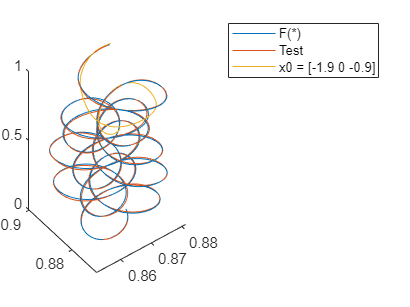

figure;
plot3(norm_data(1,1:end),norm_data(2,1:end),norm_data(3,1:end));%Plot the original normalized function
hold on;
plot3(test(1,1:end),test(2,1:end),test(3,1:end))%Plot the normalized output of the NN for the training data
hold on;
plot3(output(1,1:end),output(2,1:end),output(3,1:end))%Plot the normalized output of NN for the 200 first steps for x0=[-1.9 0 -0.9]
legend('F(*)','Test','x0 = [-1.9 0 -0.9]')

Plot the denormalized data

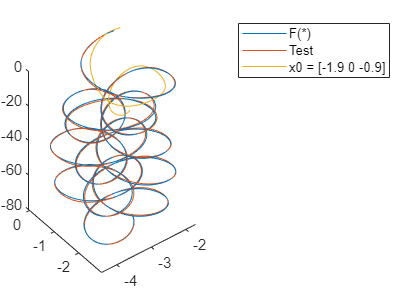

figure;
plot3(data(1,1:end),data(2,1:end),data(3,1:end))%Plot the original function
hold on;
plot3(denorm(1,1:end),denorm(2,1:end),denorm(3,1:end))%Plot the output of the NN for the training data
hold on;
plot3(denorm_out(1,1:end),denorm_out(2,1:end),denorm_out(3,1:end))%Plot the output of the NN for 200 first steps for x0=[-1.9 0 -0.9]
legend('F(*)','Test','x0 = [-1.9 0 -0.9]')